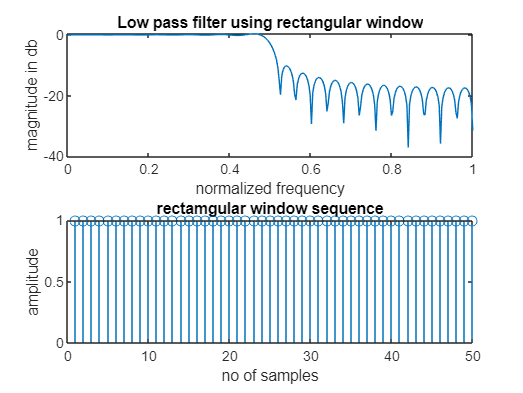

clc;
clear all;
close all;
wc = 0.5*pi;
N=50;
%N = input('enter the value of N');
alpha = (N-1)/2;
n=0:1:N-1;
hd=sin(wc*(n-alpha))./(pi*(n-alpha));
wr=boxcar(N);
hn=hd.*wr';
w=0:0.01:pi;
h=freqz(hn,1,w);
subplot(2,1,1);
plot(w/pi,10*log10(abs(h)));
title('Low pass filter using rectangular window');
xlabel('normalized frequency');
ylabel('magnitude in db');
subplot(2,1,2);
stem(wr);
title('rectamgular window sequence');
xlabel('no of samples');
ylabel('amplitude');